f = @(x) x^4-3*x^2+14*x-6;
g = @(x) x - (2*f(x))/(5*x^2);
intersezione = @(x) x;
[res, iter_err] = fixed_point_iter(f, 0.8, 10^-2, 100);
% in questo esempio la funzione g cresce troppo velocemente nel punto
% in cui g(x) interseca con la funzione y = x
% infatti il metodo ritorna NaN
% questo quasi sicuramente perche' and un certo punto esegue l'operzione
% inf - inf che genera per l'appunto NaN
hold on
fplot(f);

fplot(g);

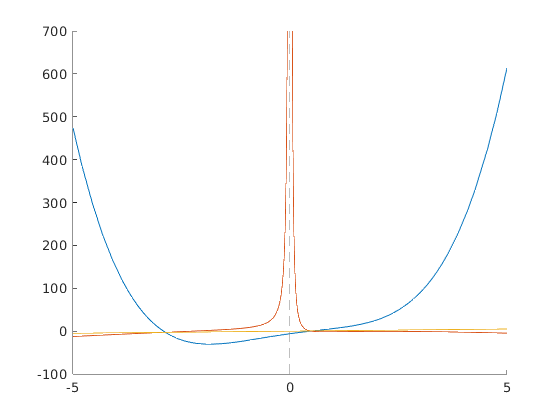

fplot(intersezione);